## ONUR POYRAZ 2010401036

## MULTILAYER PERCEPTRON MODEL

clear all;
clc;

## Create the train and test input and desired outputs

indis=randperm(100);
for i=1:100
    if i<=85
        X(i,1)=2*pi/indis(i);
        d(i,1)=sin(2*pi/indis(i));
    else
        X_test(i-85,1)=2*pi/indis(i);
        d_test(i-85,1)=sin(2*pi/indis(i));
    end
end

## User defined parameters

lf=0.05;
moment=0;
nodes=[1 10 1];

## Calculating number of layer and max layer length

layer=length(nodes)-1;
l_max=0;
samplerpattern=length(X(:,1));
for i=1:length(nodes)
    if nodes(i)>=l_max
        l_max=nodes(i);
    end
end

## Sigmoid function

sigmoid = @(x) tanh(x);
sigmoid_diff= @(x) sech(x);

## Initializing Weight and Teta Matrices

w=zeros(l_max,l_max,layer);
delta_w=zeros(l_max,l_max,layer);
delta_w_old=zeros(l_max,l_max,layer);
teta=zeros(layer,l_max);
delta_teta=zeros(layer,l_max);
delta_teta_old=zeros(layer,l_max);
for k=1:layer
    for j=1:nodes(k+1)
        for i=1:nodes(k)
            w(i,j,k)=(rand-0.5)/10;
        end
    end
end
for k=1:layer-1
    for j=1:nodes(k+1)
        teta(k,j)=(rand-0.5)/10;
    end
end

## Implementation of Algorithm

epoch=0;
while(1)
    epoch=epoch+1; %counting number of epoch
    error=zeros(1,samplerpattern);
    output=zeros(length(d(:,1)),length(d(1,:)));
    index=randperm(samplerpattern); %in each epoch this parts makes sampler patterns comes randomly
    for sample=1:samplerpattern
        s=index(sample);
        y=zeros(layer,l_max);
        y_diff=zeros(layer,l_max);
        sigma=zeros(layer,l_max);
        x=zeros(layer,l_max);
        input=X(s,:);

Calculate the Outputs and Find the Last Error at the System

        for k=1:layer
            for j=1:nodes(k+1)
                for i=1:nodes(k);
                    x(k,j)=x(k,j)+input(i)*w(i,j,k);
                end
                if k==layer
                    y(k,j)=x(k,j);
                    sigma(k,j)=d(s,j)-y(k,j);
                    output(s,j)=y(k,j);
                    error(1,s)=error(1,s)+(sigma(k,j)^2);
                else
                    x(k,j)=x(k,j)+teta(k,j);
                    y(k,j)=sigmoid(x(k,j));
                    y_diff(k,j)=sigmoid_diff(x(k,j));
                end
                error(1,s)=error(1,s)/2;
            end
            if k~=layer
                input=y(k,:);
            end
        end

Calculate Delta Weight and Delta Teta Matrices and Update Them

        for k=layer:-1:1
            for i=1:nodes(k)
                for j=1:nodes(k+1)
                    if k~=3
                        delta_teta(k,j)=lf*sigma(k,j)+moment*delta_teta_old(k,j);
                        teta(k,j)=teta(k,j)+delta_teta(k,j);
                    end
                    if k==1
                        delta_w(i,j,k)=lf*sigma(k,j)*X(s,i)+moment*delta_w_old(i,j,k);
                        w(i,j,k)=w(i,j,k)+delta_w(i,j,k);
                    else
                        delta_w(i,j,k)=lf*sigma(k,j)*y(k-1,i)+moment*delta_w_old(i,j,k);
                        w(i,j,k)=w(i,j,k)+delta_w(i,j,k);
                        sigma(k-1,i)=sigma(k-1,i)+w(i,j,k)*sigma(k,j);
                    end
                end
                if k~=1
                    sigma(k-1,i)=sigma(k-1,i)*y_diff(k-1,i);
                end
            end
        end

For momentum term this part hides the old values of delta weight

        delta_w_old=delta_w;
        delta_teta_old=delta_teta;
    end

Calculate total cost function and plot it

converged at epoch: 69


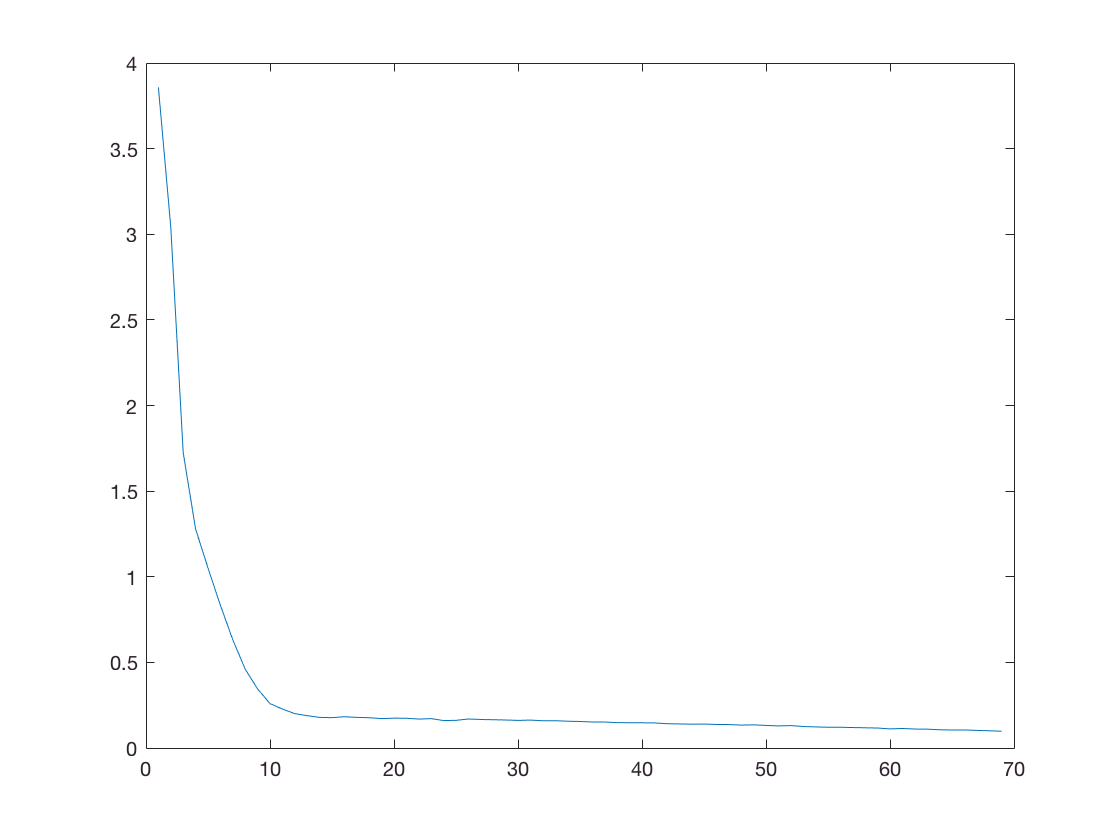

    err(epoch)=sum(error);
    figure(1);
    plot(err)
    if err(epoch)<0.05
        fprintf('converged at epoch: %d\n',epoch);
        break
    end
end

## Test Structure

out=zeros(length(d_test(:,1)),length(d_test(1,:)));
for s=1:length(d_test(:,1))
    x=zeros(layer,l_max);
    y=zeros(layer,l_max);
    in=X_test(s,:);
    for k=1:layer
        for j=1:nodes(k+1)
            for i=1:nodes(k);
                x(k,j)=x(k,j)+in(i)*w(i,j,k);
            end
            if k==layer
                y(k,j)=x(k,j);
                out(s,j)=y(k,j);
            else
                x(k,j)=x(k,j)+teta(k,j);
                y(k,j)=sigmoid(x(k,j));
            end
        end
        if k~=layer
            in=y(k,:);
        end
    end
end
percentage=((abs(d_test-out))./d_test)*100;
Desired_Actual_PercentageError=[d_test out percentage]

Desired_Actual_PercentageError =    1.0e+18 *

    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    1.1587
   -0.0000    0.0000   -0.7135
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
